# Antenna Frequency Response Report Generator

## 1 Configuration

clear;
close all;
clc;
clf;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

%cmdStyles="ieee";

cmdStyles="pptx";
cmdColorOrder = [1 0 0; 0 0 1; 0 0.4 0 ];           % https://jp.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html
%cmdColorOrder = [0 0 1; 0.4660 0.6740 0.1880; 1 0 0];           % https://jp.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html
cmdLineStyleOrder = ["-" "-" "-."];
cmdLineWidthOrder = [2; 2; 2];

savefile_types = [".png"; ".fig"; ".emf";];                     % .csv has a matrix bug.

% File selection
[file_ref, path_ref]    = uigetfile('../input_sps/*.s1p', 'Reference data');  % Reference data
[file_comp1, path_comp1]= uigetfile('../input_sps/*.s1p', 'Comp #1');         % Compared data #1
[file_comp2, path_comp2]= uigetfile('../input_sps/*.s1p', 'Comp #2');         % Compared data #2
abs_file_ref   = string(append(path_ref,file_ref));
abs_file_comp1 = string(append(path_comp1,file_comp1));
abs_file_comp2 = string(append(path_comp2,file_comp2));

dir_output = string(path_ref);

% S-parameter file list. The number of processing data is set with the length of this string.
filenames_toload    = [abs_file_ref; abs_file_comp1; abs_file_comp2];
alternate_filenames = ["Simulation"; "Measurement"; "Measurement Exp02"];

% --- Style #1
% cmdXlim_GHz = [1;12];
% cmdLineStyleOrder = ["-" "-" "--"];
% cmdLineWidthOrder = [2; 2; 1];

% --- Style #2
% cmdXlim_GHz = [1;10];
% smith1_range = [3.16; 8.15];
% smith2_range = [3.16; 8.15];

% --- Style #3
%cmdXlim_GHz = [1;12];
%smith1_range = [3.607; 14.50];
%smith2_range = [3.607; 14.50];

% --- Style #4
cmdXlim_GHz = [1;12];
smith1_range = [3.607; 14.50];
smith2_range = [3.607; 14.50];

## 2 Return Loss [dB]

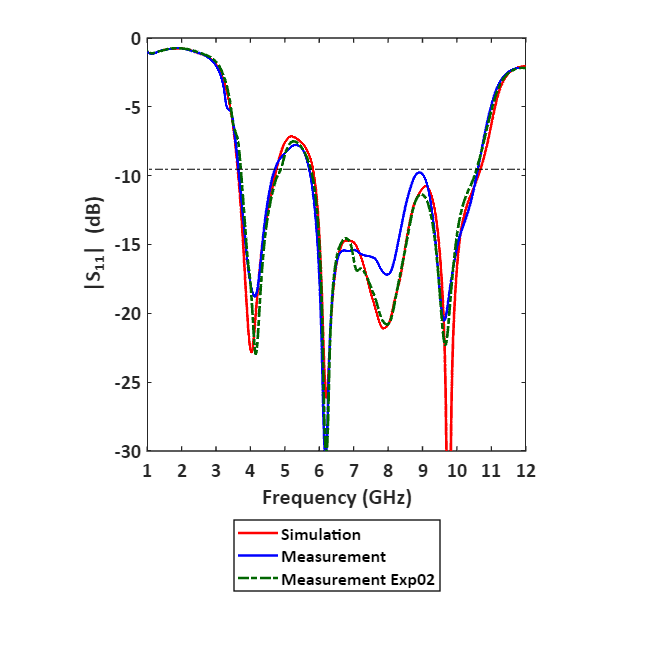

cmd_genfig_s11_logmag(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,"vswr2");

## 3 VSWR

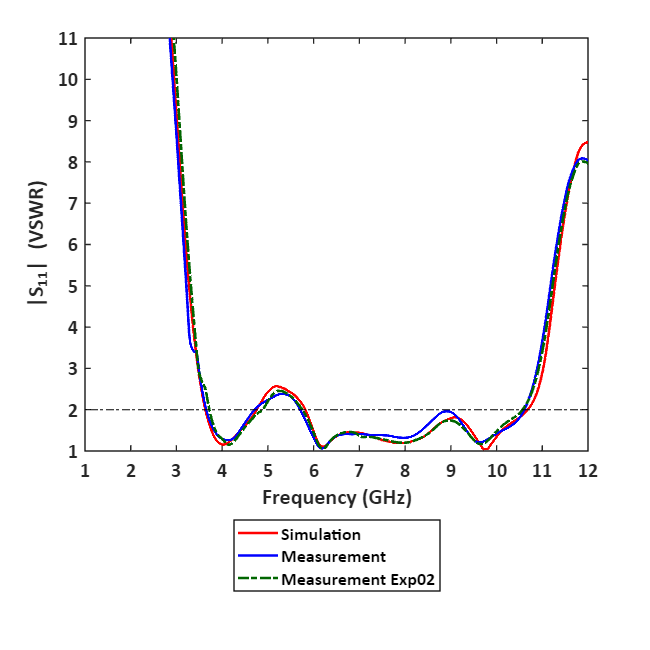

cmd_genfig_s11_vswr(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder, "vswr2");

## 4 Z Parameters

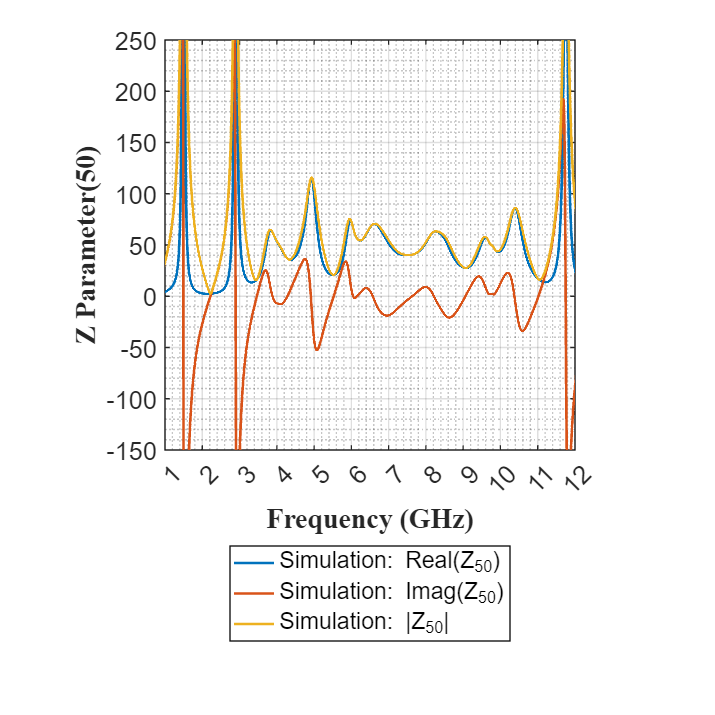

cmd_genfig_s11_zparam(dir_output, filenames_toload(1), alternate_filenames(1), cmdXlim_GHz, cmdStyles, savefile_types, [0 0 1; 1 0 0; 0.4660 0.6740 0.1880], cmdLineStyleOrder, cmdLineWidthOrder);

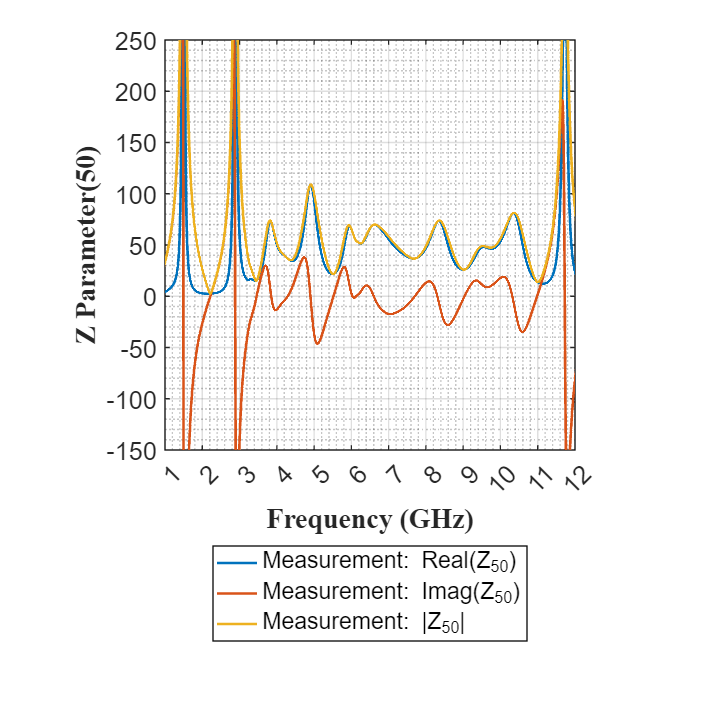

cmd_genfig_s11_zparam(dir_output, filenames_toload(2), alternate_filenames(2), cmdXlim_GHz, cmdStyles, savefile_types, [0 0 1; 1 0 0; 0.4660 0.6740 0.1880], cmdLineStyleOrder, cmdLineWidthOrder);

## 5 S11 Smith Chart (full-range)

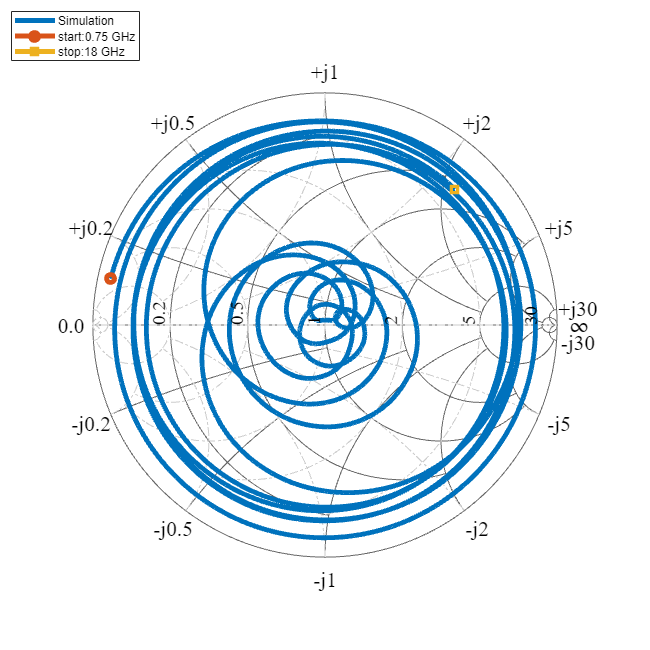

cmd_genfig_s11_smith(dir_output, filenames_toload(1), alternate_filenames(1), "auto", cmdXlim_GHz, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

## 6 S11 Smith Chart (reduced-range)

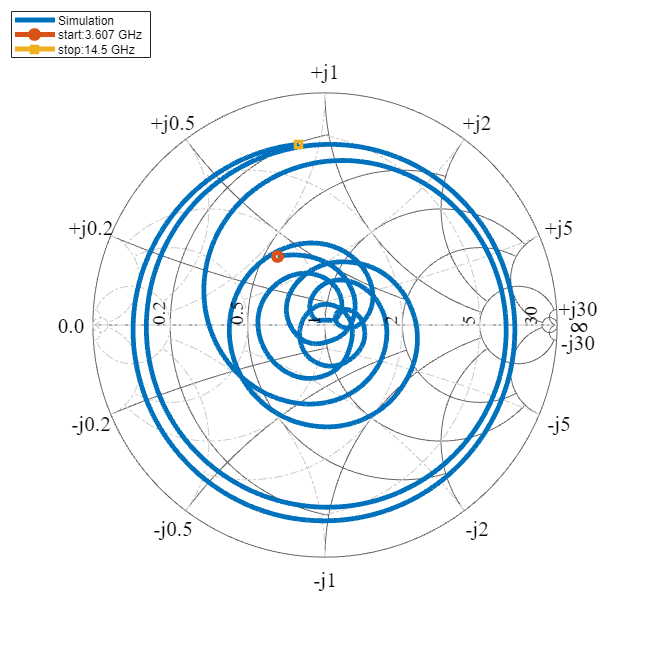

cmd_genfig_s11_smith(dir_output, filenames_toload(1), alternate_filenames(1), "man", smith1_range, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

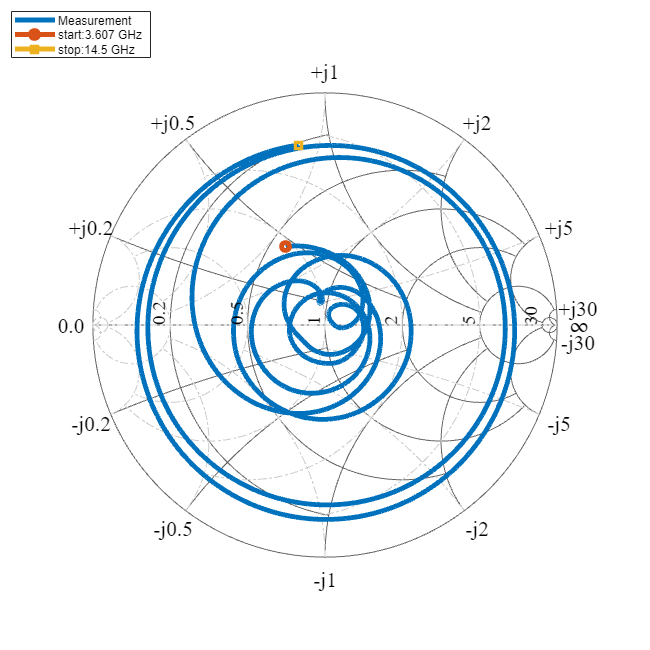

%cmd_genfig_s11_smith(dir_output, filenames_toload(2), alternate_filenames(2), "man", smith1_range, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

% error: creating .csv file.. cmd_genfig_s11_smith(dir_output, filenames(1), "man", [1.5;2.5], cmdStyles, [".csv";".png"], cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

## 7 S11 Phase (unwrapped)

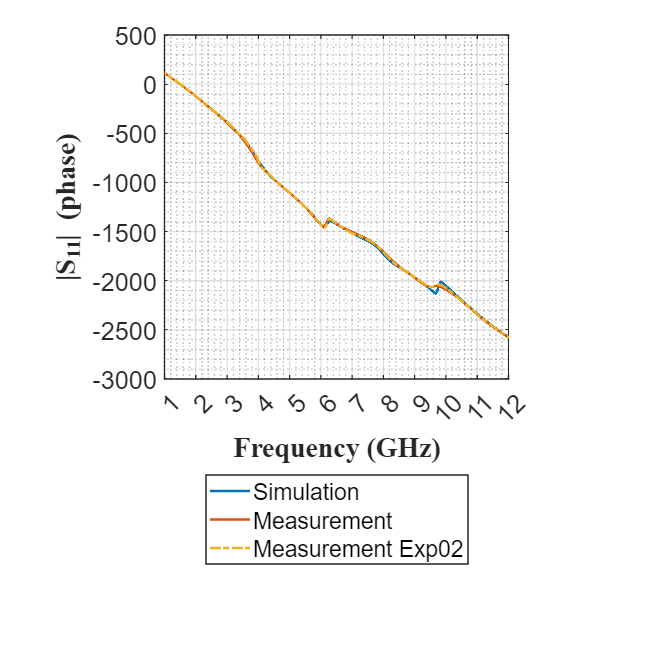

cmd_genfig_s11_phase(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,1);

## 8 S11 Phase (wrapped)

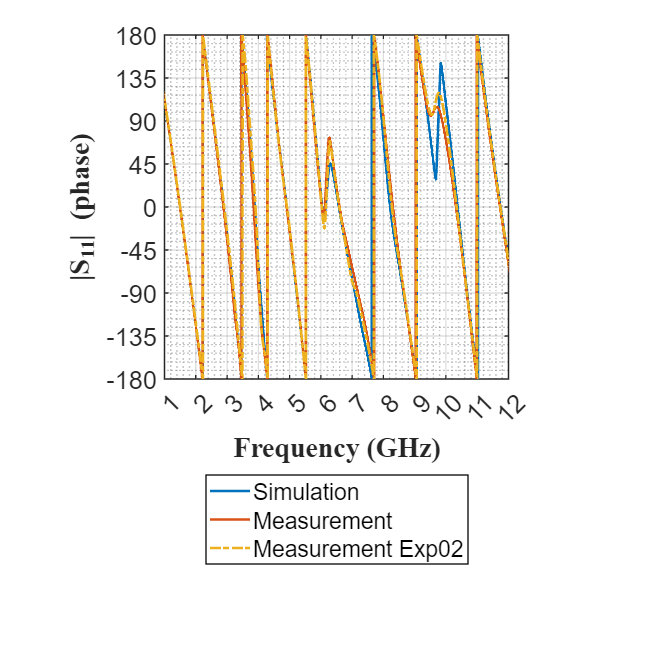

cmd_genfig_s11_phase(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,0);